# Криптографія. Лабораторна робота 1.

## Експерементальна оцінка ентропії на символ джерела

### Текст та форматування

Як середньостатистичний текст середньостатистичною російською мовою середньостатистичного росіянина ми взяли ~500000 символів (~1Мб) тексту ниття терориста та військового злочинця${\;}_{\mathrm{i}} \mathrm{горя}{\;\;}_{\mathrm{c}} \mathrm{трєлкова}-_{\mathrm{г}} \mathrm{іркіна}$ з його телеграм-каналу.

Зчитуємо текст в змінну-рядок:

text = fileread('girkin.txt');

Форматуваємо текст (видалення зайвих символів та зайвих пробілів):

formated_text = blanks(length(text));

for i = 1:length(text)
    c = text(i);
    if (c <= 'я' && c >= 'а') || c == ' '
        formated_text(i) = c;
    elseif (c <= 'Я' && c >= 'А')
        formated_text(i) = char(c + 0x0020);
    elseif c == 'Ё' || c == 'ё'
        formated_text(i) = 'е';
    else
        formated_text(i) = ' ';
    end
end

mask = (formated_text == ' ');
mask = ~(mask & [0 mask(1:end-1)]);
formated_text2 = formated_text(mask);

*Оригінальний (файл *`girkin.txt`*) та кінцевий форматований текст (змінна *`formated_text2`*) мають бути десь разом з цим файлом.*

### Робота з форматованим текстом

Створюємо два відображення типу "символ -> кількість входжень в тексті" та "біграма -> кількість входжень в тексті":

bigrams = dictionary(string([]), []);
chars = dictionary(string([]), []);

Заповнюємо дані про **окремі символи** :

for i = 1:length(formated_text2)
    c1 = formated_text2(i);
    if chars.isKey(c1)
        chars(c1) = chars(c1) + 1;
    else
        chars(c1) = 1;
    end
end
chars;

Заповнюємо дані про **біграми** :

for i = 1:(length(formated_text2)-1)
    c2 = [formated_text2(i) formated_text2(i+1)];

    if bigrams.isKey(c2)
        bigrams(c2) = bigrams(c2) + 1;
    else
        bigrams(c2) = 1;
    end
end
bigrams;

*Ці зібрані дані прикладені окремими файлами (див. нижче)*

### Обчислення ентропій $H_1$ та $H_2$

t1 = chars.values / sum(chars.values);
H1 = -sum(t1 .* log2(t1))

H1 = 4.3851


t_b = bigrams.values / sum(bigrams.values);
H2 = -sum(t_b .* log2(t_b)) * 0.5

H2 = 3.9881

### Оцінки для $H^{\left(10\right)} ,\;\;H^{\left(20\right)} ,\;H^{\left(30\right)}$ та обчислення надлишковості мови

За допомогою `CoolPinkProgram.exe обчислимо `$H^{\left(10\right)} ,\;\;H^{\left(20\right)} ,\;H^{\left(30\right)}$ :

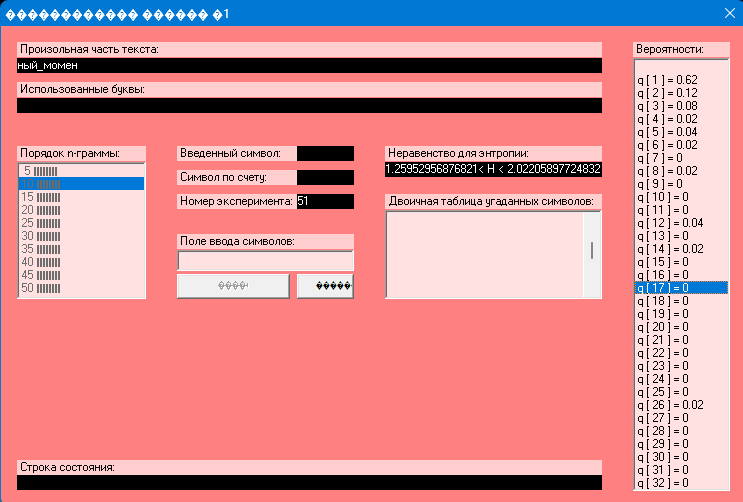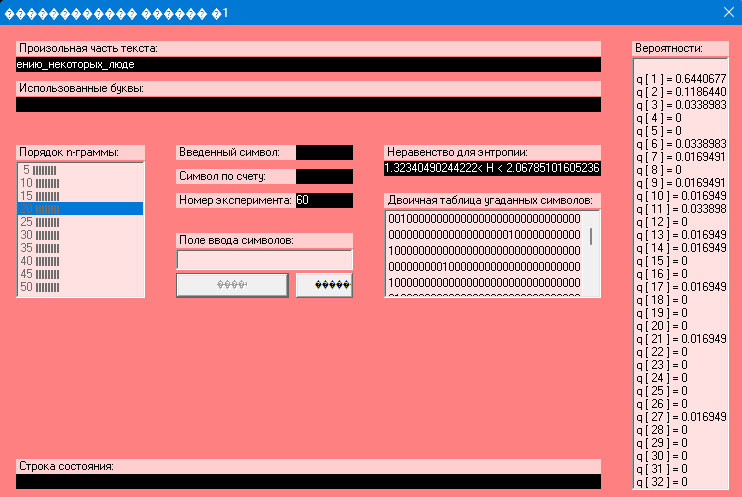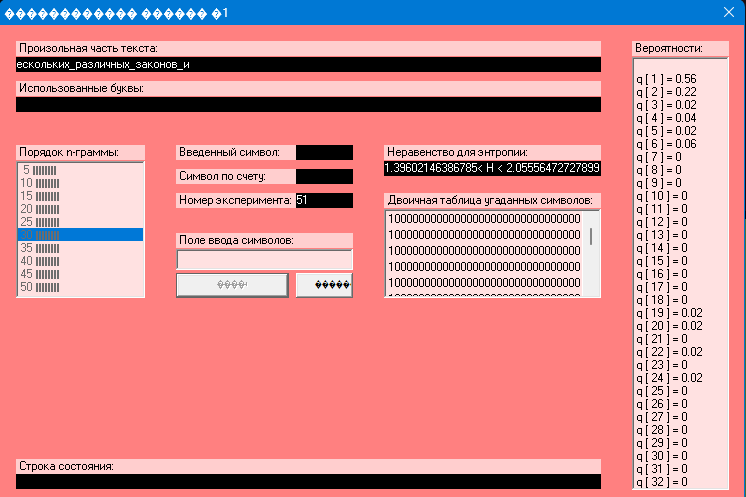

Отже, маємо такі результати :


$$\begin{array}{l}
1\ldotp 26\;\le \;H^{\left(10\right)} \le \;2\ldotp 02\\
1\ldotp 32\le \;\;H^{\left(20\right)} \le \;2\ldotp 07\;\\
1\ldotp 40\le \;H^{\left(30\right)} \;\le 2\ldotp 06
\end{array}$$


Візьмемо $H^{\left(30\right)}$ як найкраще наближення для $H_{\infty }$, тоді обчислимо надлишковість російської мови $R$ за формулою :

$R\;=\;1-\frac{H_{\infty } }{H_0 }\;$,    де $H_0 \;=\log_2 \left(32\right)=5$

Тоді надлишковість $R$ буде в таких межах :


$$0\ldotp 58\;\le \;\;R\;\;\le 0\ldotp 72$$


Тобто маємо **надлишковість російської мови в районі 65%.**

### Візуалізація

Наступний код потрібен лише для красивих табличок з даними (які також мають бути десь разом з цим файлом) і ніякого іншого корисного навантаження не несе.

(можна було б зробити ці таблички інтерактивними прямо тут, але це занадто складно, а результат не вартує того)

keys_c = chars.keys;
values_c = chars.values;
[sortedValues_c, sortInd_c] = sort(values_c);
sortedKeys_c = keys_c(sortInd_c);

%-------------------------------------

svalues1 = zeros(32, 1);

for i = 1:32
    for j = 1:32
        b = string([char(i + 'а' - 1) char(j + 'а' - 1)]);

        if bigrams.isKey(b)
            svalues1(i) = svalues1(i) + bigrams(b);
        end
    end
end

alph = 'абвгдежзийклмнопрстуфхцчшщъыьэюя';

[~, sortInd1] = sort(svalues1);

alph = alph(sortInd1);

bfreq_matrix = zeros(32, 32);

for i = 1:32
    for j = 1:32
        b = string([alph(i) alph(j)]);

        if bigrams.isKey(b)
            bfreq_matrix(i, j) = bigrams(b);
        end
    end
end
